# Phytoplankton Growth

## Example designed to practice non-linear regression

This example is designed to demonstrate how to perform nonlinear regression and compare uncertainties in model coefficients for nonlinear regression.

Using data collected for phytoplankton cell counts over time from a bottle incubation experiment we will fit a growth model. If phytoplankton are provided sufficient light and nutrients, growth can be modeled as a first-order process as

$\frac{\partial }{\partial t}P=\mu P$.

where P is in (cells/ml) and $\mu$ is the specific growth rate with units of 1/time.

Integrating, we can solve for P with respect to time as

$P=P_0 \exp \left(\mu t\right)$.

## Load and inspect the data.

First we load the data into the workspace and then plot it.

The data is saved as a *.mat file and will be loaded as two arrays, variable `x` is time in days since 2001-1-1 (UTC), and y the corresponding data collected as chlorophyll fluorescence ($\mu$g/L).

load phyto_growth_chl

Plotting data on linear axes should reveal a pattern that looks to possibly follow an exponential function. As we discussed in lecture, growth may follow this classic model, or it may follow a power law in cases where other factors effecting growth are changing, for example inceasing resources allowing for super-exponential growth.

A quick way to inspect the data is to plot the data on linear and log axes. For example, an exponential function will plot linear on semi-log axes. So, if you plot the data with chl plotted on a logarithm axes (as the dependent or `y`-axis), and time in days plotted linearly (as the independent or `x`-axis), it will appear linear if the data follow the exponential growth function. The trend is linear if both axes are plotted on log scales for power law trend.

Inspect the data and see what you discover. First open variable `y` and notice there are several missing values entered as NaN (non a number) in the series of 1181 entries. We can perform QC on the data and clean up the NaNs in `y` before plotting.

bad = find(isnan(y));
y(bad) = [];
x(bad) = [];

After cleaning up the data, we are left with 295 values of Chl. Next let's modify `x` so that time is set to be relative to begining of the data set.

x = x-x(1);

Plot the data on linear, semilog and log-log to inspect the shape.

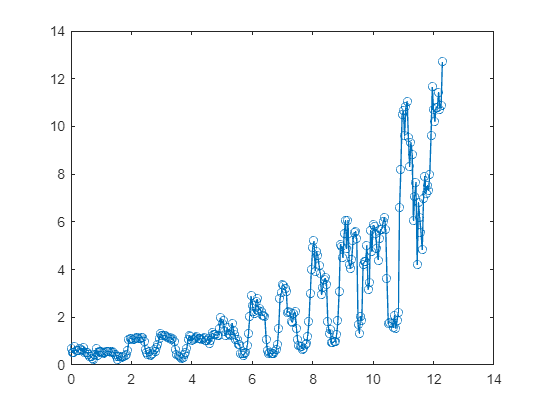

figure
plot(x,y,'o-')

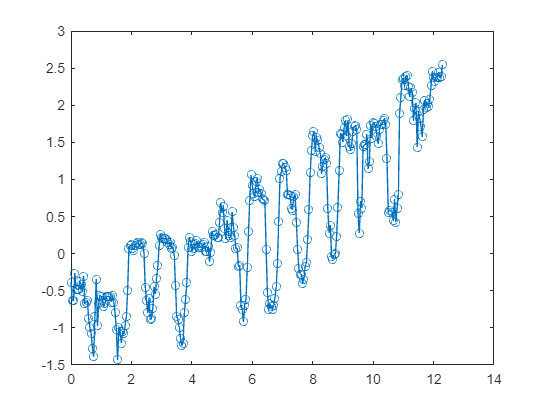

figure
plot(x,log(y),'o-')

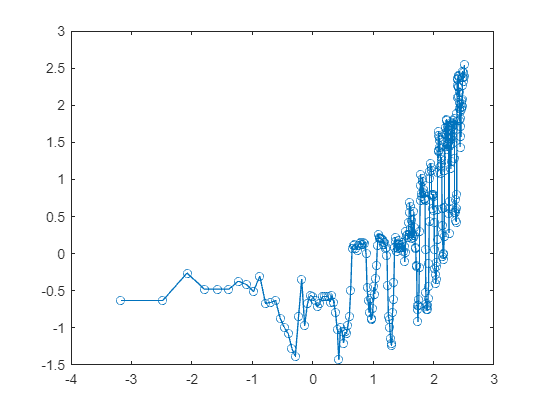

figure
plot(log(x),log(y),'o-')

It is hard to tell which model would fit better based on inspection, but it appears exponential does a reasonable job for this data. So let's move forward with fitting, starting with the expected exponential function.

## Nonlinear fitting

Since our model is non-linear we will use the non-linear least squares fitting routine `nlleasqr.m`

The routine is called with the following statement:

`[f,a,kvg,iter,corp,covp,covr,stdresid,Z,r2] = nlleasqr(x,y,ain,'func``_n``ame');`

with input parameters `x`, `y` representing our data, `ain` is a vector that with the initial guess of our parameters, and `func``_n``ame` is the name of a MATLAB fuction that contains our model.

To use this we will need to define a fuction `modfunc.m` and we will also need `dfdp.m`.

The fuction should contain the form of the exponential we defined above. See the m-file and ensure all the axillary functions are located in the working directory shown in the workspace `current folder`.

Reviewing `modfunc.m` we see it has the exponential form with `x` representing time and `a` vector a with two values representing the coefficients.

`--------------------------`

`fuction out = modfunc(x,a)`

`out = a(1)``*e``xp(a(2)*x);`

`---------------------------`

To perform the nonlinear fitting, we need to first guess values for the parameters, $P_0$ and $\mu$. Let's replot the data to make a reasoned guess.

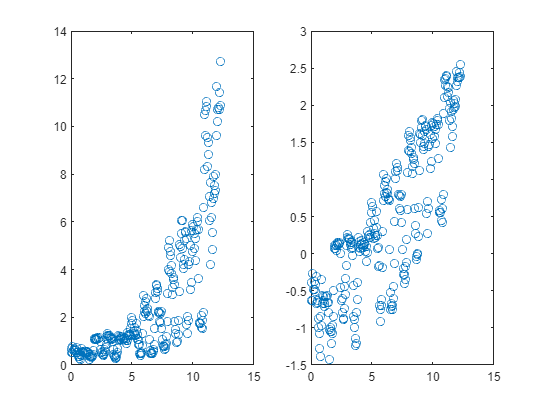

figure
subplot(1,2,1)
plot(x,y,'o')
subplot(1,2,2)
plot(x,log(y),'o')

You may want to generate a graphic to include in a separate report using the following command. You may first want to add axes labels and increase the font size to make the text easier to read.

`print(gcf,'phyto``_1``','-dpng')`

Alternantively using live script in MATLAB, we can publish this workflow directly to PDF.

Looking at the plot we may convince ourselves that the initial population $P_0$ is approximately 0.2 and the specific growth rate $\mu$ is 0.2 (doubling in five days).

ain = [0.2 0.2]

ain =     0.2000    0.2000


Plot the initial guess model with the data.

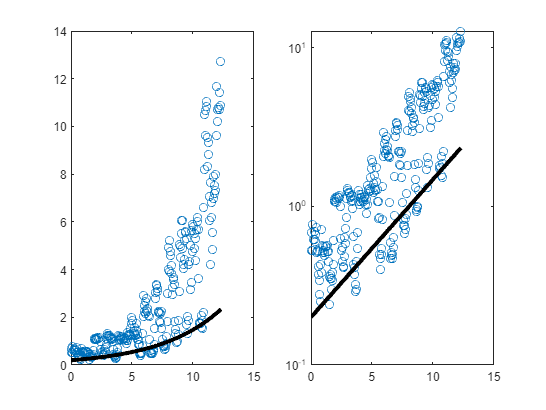

figure
subplot(1,2,1)
plot(x,y,'o')
hold on
plot(x,modfunc(x,ain),'k','LineWidth',3)

subplot(1,2,2)
semilogy(x,y,'o')
hold on
semilogy(x,modfunc(x,ain),'k','LineWidth',3)


% print(gcf,'phyto_2','-dpng')

NOW FIT to model function a1*exp(a2*t)

Note: First we must create a matlab function for this model in our case called modfunc1.m then use nlleasqr look at >> help nlleasqr to learn about input/output parameters but don't get intimidated for now, call as below

[f,a,kvg,iter,corp,covp,covr,stdresid,Z,r2] = nlleasqr(x,y,ain,'modfunc');

We'll only look at a few of the output parameters:

a is your optimal parameter vector

Let's see how much better it a does:

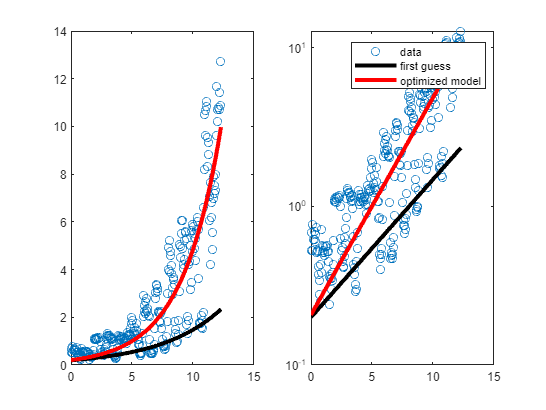

figure
subplot(1,2,1)
plot(x,y,'o')
hold on
plot(x,modfunc(x,ain),'k','LineWidth',3)
plot(x,modfunc(x,a),'r','LineWidth',3)
%
subplot(1,2,2)
semilogy(x,y,'o')
hold on
semilogy(x,modfunc(x,ain),'k','LineWidth',3)
semilogy(x,modfunc(x,a),'r','LineWidth',3)
legend('data','first guess','optimized model')


%Note we can move the legend to a better part of the plot that doesn't
%obstruct the data with the following. Uncomment to see what happens.
%legend('data','first guess','optimized model','Location','southeast')

% print(gcf,'phyto_3','-dpng')

Regarding the other parameters that are useful:

`kvg` is a flag to say whether convergence was achieved before the routine gave up

`iter` is the number of iterations that was used

`covp` is the covariance matrix of the coefficients (the square roots of the diagonal elements are the uncertainties (the sigmas) of the coefficients)

`r2` is the overall correlation coefficient

coefficients = a'

coefficients =     0.2070    0.3152


sigmas = sqrt(diag(covp))'

sigmas =     0.0307    0.0137


R2 = r2

R2 = 0.7799

The fitting parameters are the following:

`coefficients = 0.2070 0.3152`

`sigmas = 0.0307 0.0137`

`R2 = 0.7799`

So, in summary  $\mu =0\ldotp 31\pm$0.03 per day and 78% of the variability in the data is explained by the model.

How would the power law model do at representing the data.


$$\frac{\partial }{\partial t}P=a\left(t^b \right)$$


Define a new modified function with a power function and see how it looks.

%